% CDF for the probability the battery empties/fills at time T
clear all
syms E T sigma_P dt
CDF = 1 + erf(-E/(sqrt(2*T)*2*sigma_P*dt))

$$CDF = 1-\mathrm{erf}\left(\frac{\sqrt{2}\,\text{E}}{4\,\sqrt{T}\,\mathrm{dt}\,\sigma_{P}}\right)$$

CDF_const = subs(CDF,E/(sigma_P*dt),1)

$$CDF\_const = 1-\mathrm{erf}\left(\frac{\sqrt{2}}{4\,\sqrt{T}}\right)$$

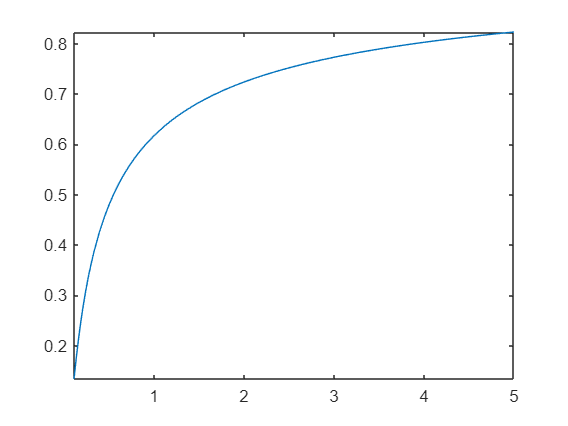

fplot(CDF_const)


% take derivative of CDF to get PDF
PDF = diff(CDF,T)

$$PDF = \frac{\sqrt{2}\,\text{E}\,{\mathrm{e}}^{-\frac{{\text{E}}^{2}}{8\,T\,{\mathrm{dt}}^{2}\,{\sigma_{P}}^{2}}}}{4\,T^{3/2}\,\mathrm{dt}\,\sigma_{P}\,\sqrt{\pi }}$$

PDF_const = subs(PDF,E/(sigma_P*dt),1)

$$PDF\_const = \frac{\sqrt{2}\,{\mathrm{e}}^{-\frac{1}{8\,T}}}{4\,T^{3/2}\,\sqrt{\pi }}$$

fplot(PDF_const)

% set derivative of PDF = 0 to get mode
dPDF = diff(PDF,T)

$$dPDF = \frac{\sqrt{2}\,{\text{E}}^{3}\,{\mathrm{e}}^{-\frac{{\text{E}}^{2}}{8\,T\,{\mathrm{dt}}^{2}\,{\sigma_{P}}^{2}}}}{32\,T^{7/2}\,{\mathrm{dt}}^{3}\,{\sigma_{P}}^{3}\,\sqrt{\pi }}-\frac{3\,\sqrt{2}\,\text{E}\,{\mathrm{e}}^{-\frac{{\text{E}}^{2}}{8\,T\,{\mathrm{dt}}^{2}\,{\sigma_{P}}^{2}}}}{8\,T^{5/2}\,\mathrm{dt}\,\sigma_{P}\,\sqrt{\pi }}$$

T_mode = solve(dPDF == 0,T)

$$T\_mode = \frac{{\text{E}}^{2}}{12\,{\mathrm{dt}}^{2}\,{\sigma_{P}}^{2}}$$

T_mode_const = subs(T_mode,E/(sigma_P*dt),1)

$$T\_mode\_const = \frac{1}{12}$$

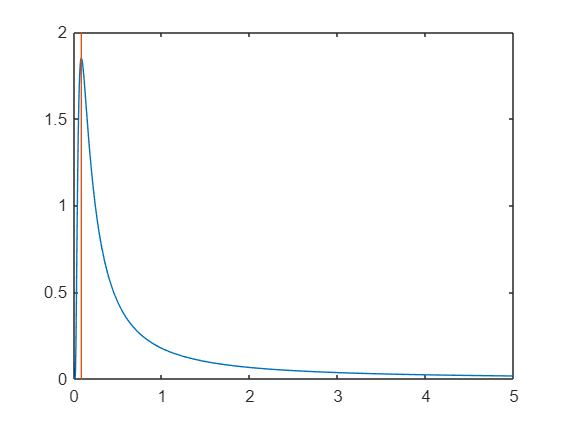

hold on
plot([T_mode_const T_mode_const],[0 2])